# **Matlab案例代码解析**

## 4. 图像信号处理案例

### 4.3 知乎提问

#### 4.3.1 matlab如何将图a中某一部分复制到图b中的相同位置上？

原问题：[https://www.zhihu.com/question/526137288/answer/2424640899](https://www.zhihu.com/question/526137288/answer/2424640899)

# matlab如何将图a中某一部分复制到图b中的相同位置上？

请问有大佬知道怎么用matlab把这张图a上任一个黑色部分，比如橙色线圈起来的部分（橙色线是a图上没有的)，画到另一张和a图大小相同的白图b上，且位置和a图上相同？

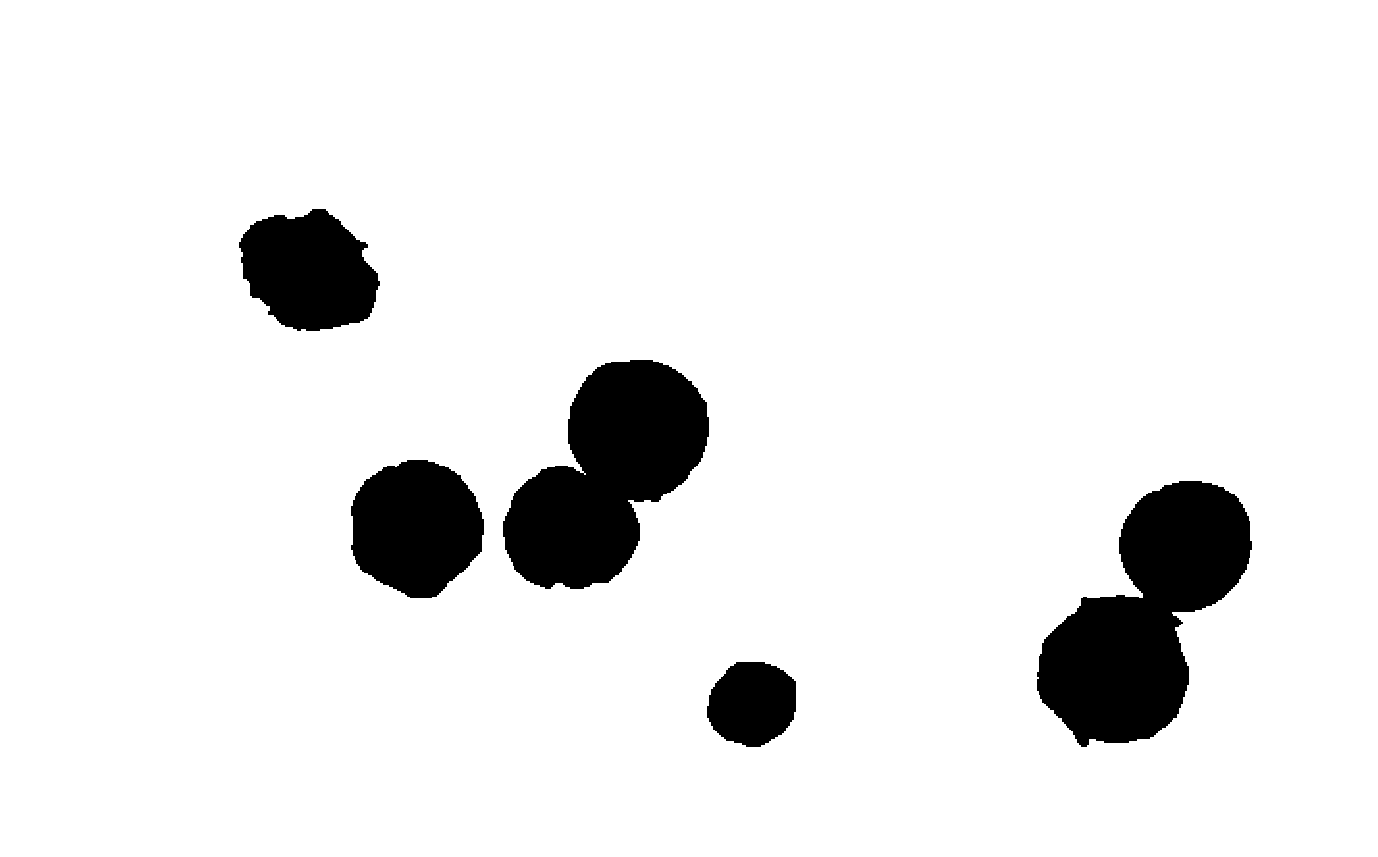

clear;clc;
img = imread('data\test.jpg');
data = rgb2gray(img);
imshow(data);

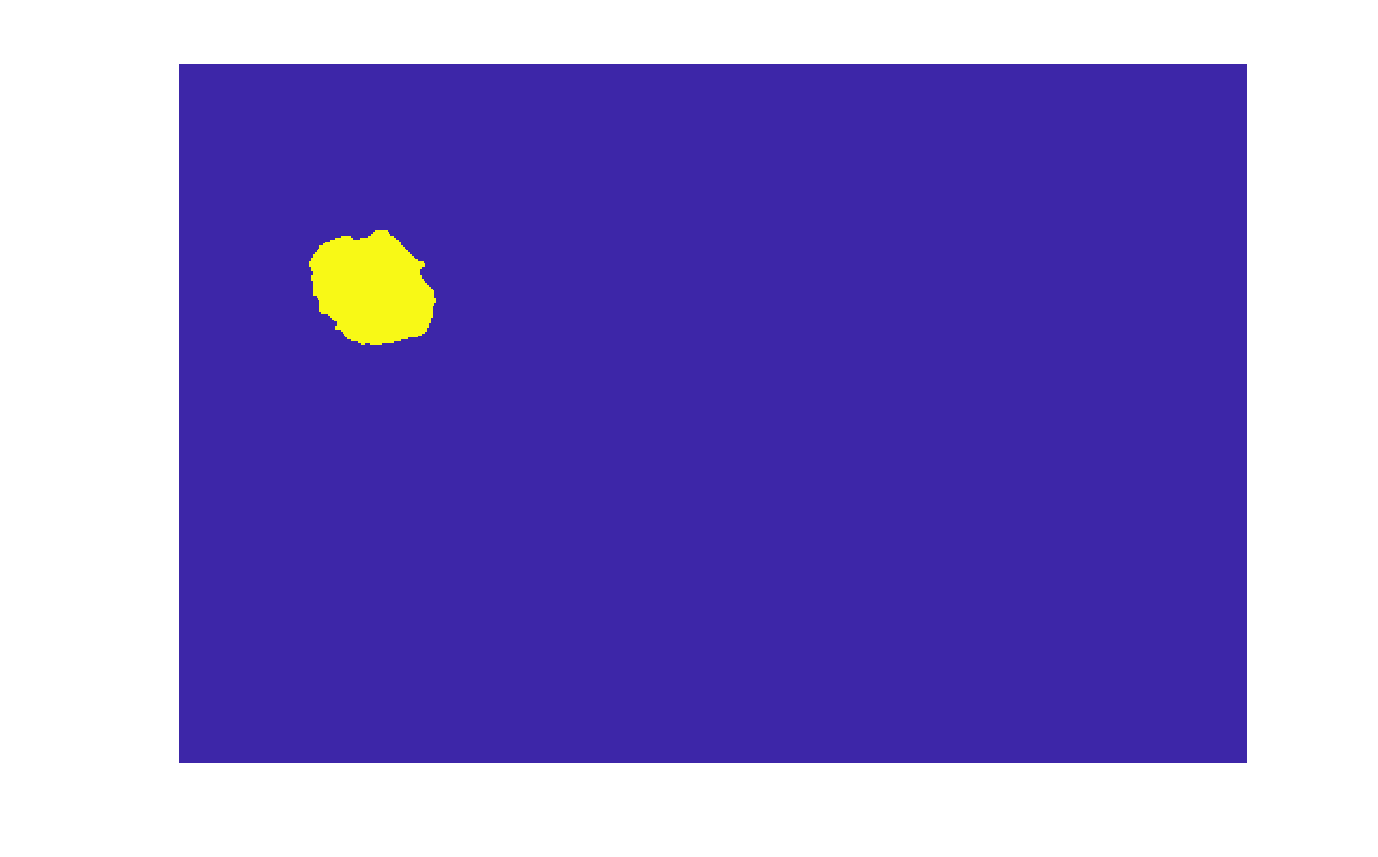

x = 214;
y = 236;
% 获取 ROI
J = 255 * RegionGrowing(data, [x, y], 20);
image(J);
axis off